# Surfaces defined by parametric functions

Finally, a more general representation of a surface involves expressing its coordinates in terms of two independent variables


$$x = f(u,v), y = g(u,v), z = h(u,v)$$


where u and v take values in some domain in 2D. For example, if we restrict $u \in [a,b]$ and $v \in [c,d]$ then the domain in the uv-plane is a rectangle. At each point in this rectangle, we determine the coordinates (x,y,z), and if we glue all of these points together then we define a parametric surface in the xyz-space. For example,


$$x = \sin u \cos v, y = \sin u \sin v, z = \cos u, u \in [0,\pi], v \in [0,2\pi]$$


defines a sphere of radius 1, centered at the origin. In order to visualize this in Matlab we first define a mesh grid in the uv-domain

u = linspace(0,2*pi,100)

u =          0    0.0635    0.1269    0.1904    0.2539    0.3173    0.3808    0.4443    0.5077    0.5712    0.6347    0.6981    0.7616    0.8251    0.8885    0.9520    1.0155    1.0789    1.1424    1.2059    1.2693    1.3328    1.3963    1.4597    1.5232    1.5867    1.6501    1.7136    1.7771    1.8405    1.9040    1.9675    2.0309    2.0944    2.1579    2.2213    2.2848    2.3483    2.4117    2.4752    2.5387    2.6021    2.6656    2.7291    2.7925    2.8560    2.9195    2.9829    3.0464    3.1099


v = linspace(0,2*pi,100)

v =          0    0.0635    0.1269    0.1904    0.2539    0.3173    0.3808    0.4443    0.5077    0.5712    0.6347    0.6981    0.7616    0.8251    0.8885    0.9520    1.0155    1.0789    1.1424    1.2059    1.2693    1.3328    1.3963    1.4597    1.5232    1.5867    1.6501    1.7136    1.7771    1.8405    1.9040    1.9675    2.0309    2.0944    2.1579    2.2213    2.2848    2.3483    2.4117    2.4752    2.5387    2.6021    2.6656    2.7291    2.7925    2.8560    2.9195    2.9829    3.0464    3.1099


[U,V] = meshgrid(u,v)

U =          0    0.0635    0.1269    0.1904    0.2539    0.3173    0.3808    0.4443    0.5077    0.5712    0.6347    0.6981    0.7616    0.8251    0.8885    0.9520    1.0155    1.0789    1.1424    1.2059    1.2693    1.3328    1.3963    1.4597    1.5232    1.5867    1.6501    1.7136    1.7771    1.8405    1.9040    1.9675    2.0309    2.0944    2.1579    2.2213    2.2848    2.3483    2.4117    2.4752    2.5387    2.6021    2.6656    2.7291    2.7925    2.8560    2.9195    2.9829    3.0464    3.1099
         0    0.0635    0.1269    0.1904    0.2539    0.3173    0.3808    0.4443    0.5077    0.5712    0.6347    0.6981    0.7616    0.8251    0.8885    0.9520    1.0155    1.0789    1.1424    1.2059    1.2693    1.3328    1.3963    1.4597    1.5232    1.5867    1.6501    1.7136    1.7771    1.8405    1.9040    1.9675    2.0309    2.0944    2.1579    2.2213    2.2848    2.3483    2.4117    2.4752    2.5387    2.6021    2.6656    2.7291    2.7925    2.8560    2.9195    2.9829    3.0464    3

V =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0.0635    0

Now we define a function that defines the parametric equations for the sphere. You will find it at the end of this script, but we copy it here for clarity

**function [x,y,z] = sphereparam(u,v)**

**    x = sin(u) cos(v)**

**    y = sin(u) sin(v)**

**    z = cos(u)**

**end**

Now we can call the function, and then use **surf** to visualize the sphere.

[X,Y,Z] = sphereparam(U,V)

X =          0    0.0634    0.1266    0.1893    0.2511    0.3120    0.3717    0.4298    0.4862    0.5406    0.5929    0.6428    0.6901    0.7346    0.7761    0.8146    0.8497    0.8815    0.9096    0.9341    0.9549    0.9718    0.9848    0.9938    0.9989    0.9999    0.9969    0.9898    0.9788    0.9638    0.9450    0.9224    0.8960    0.8660    0.8326    0.7958    0.7557    0.7127    0.6668    0.6182    0.5671    0.5137    0.4582    0.4009    0.3420    0.2817    0.2203    0.1580    0.0951    0.0317
         0    0.0633    0.1263    0.1889    0.2506    0.3114    0.3709    0.4289    0.4852    0.5396    0.5917    0.6415    0.6887    0.7331    0.7746    0.8129    0.8480    0.8797    0.9078    0.9323    0.9530    0.9699    0.9828    0.9918    0.9969    0.9979    0.9948    0.9878    0.9768    0.9619    0.9431    0.9205    0.8942    0.8643    0.8309    0.7942    0.7542    0.7113    0.6654    0.6169    0.5659    0.5126    0.4573    0.4001    0.3413    0.2812    0.2199    0.1577    0.0949    0

Y =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0040    0.0080    0.0120    0.0159    0.0198    0.0236    0.0273    0.0308    0.0343    0.0376    0.0408    0.0438    0.0466    0.0492    0.0517    0.0539    0.0559    0.0577    0.0592    0.0606    0.0616    0.0625    0.0630    0.0634    0.0634    0.0632    0.0628    0.0621    0.0611    0.0599    0.0585    0.0568    0.0549    0.0528    0.0505    0.0479    0.0452    0.0423    0.0392    0.0360    0.0326    0.0291    0.0254    0.0217    0.0179    0.0140    0.0100    0.0060    0

Z =     1.0000    0.9980    0.9920    0.9819    0.9679    0.9501    0.9284    0.9029    0.8738    0.8413    0.8053    0.7660    0.7237    0.6785    0.6306    0.5801    0.5272    0.4723    0.4154    0.3569    0.2969    0.2358    0.1736    0.1108    0.0476   -0.0159   -0.0792   -0.1423   -0.2048   -0.2665   -0.3271   -0.3863   -0.4441   -0.5000   -0.5539   -0.6056   -0.6549   -0.7015   -0.7453   -0.7861   -0.8237   -0.8580   -0.8888   -0.9161   -0.9397   -0.9595   -0.9754   -0.9874   -0.9955   -0.9995
    1.0000    0.9980    0.9920    0.9819    0.9679    0.9501    0.9284    0.9029    0.8738    0.8413    0.8053    0.7660    0.7237    0.6785    0.6306    0.5801    0.5272    0.4723    0.4154    0.3569    0.2969    0.2358    0.1736    0.1108    0.0476   -0.0159   -0.0792   -0.1423   -0.2048   -0.2665   -0.3271   -0.3863   -0.4441   -0.5000   -0.5539   -0.6056   -0.6549   -0.7015   -0.7453   -0.7861   -0.8237   -0.8580   -0.8888   -0.9161   -0.9397   -0.9595   -0.9754   -0.9874   -0.9955   -0

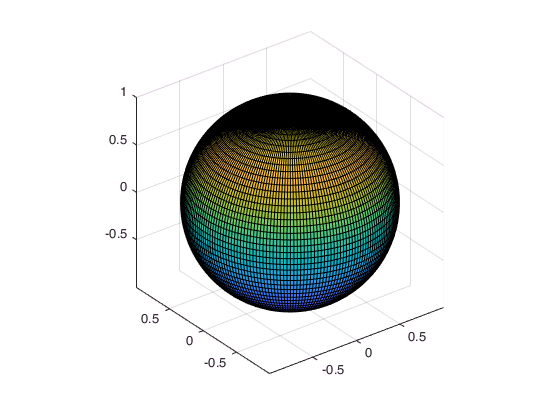

surf(X,Y,Z)
axis equal

**Exercise 1: **Consider the following parametric equations


$$x = (a + r \cos u) \cos v, y = (a+r\cos u) \sin v, z = r \sin u
$$


with r < a, and defined on the domain $u \in [0, 2\pi], v \in [0, 2\pi] $.

- Write a function that accepts u,v,a, and r as inputs, and returns x,y, and z.

- Visualize the surface for some different values of a and r.

- What features of the surface do the parameters r and a control?

 **Answer: **

When a = 0, the shape is a sphere with radius = r

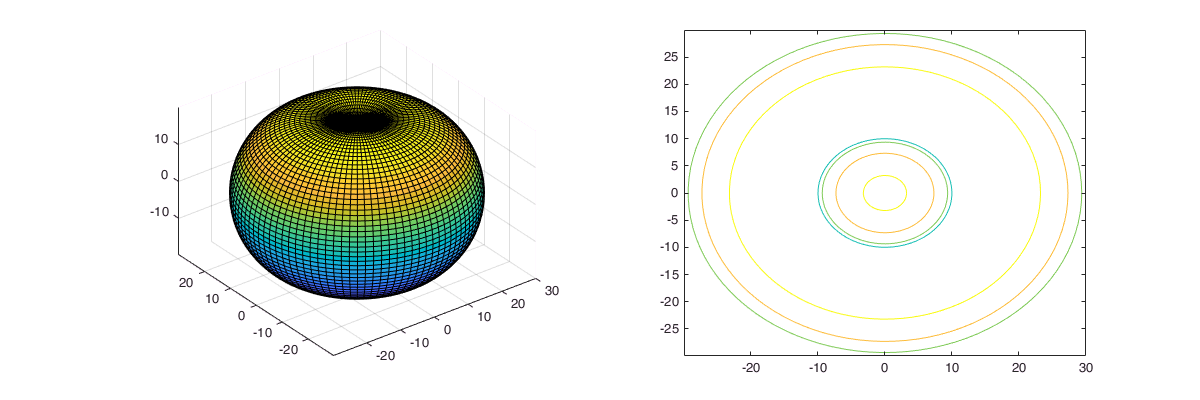

a = 0; r = 50;
[X, Y, Z] = shape(U, V, 0, 50);
figure('Position', [100, 100, 1200, 400]);
subplot(1,2,1);
surf(X,Y,Z)
axis equal
subplot(1,2,2);
contour(X,Y,Z)

 When **a** is present, the sphere begins to shrink vertically and there appears a hole in it. Appropriate values of** a** and **r** will make a donut! 

After trying different values of** r** with** a constant value of a**, my best guess is that** r = the radius of the donut - the radius of the center hole **and determines **how thick the donut would be**

Then I figured out that **a** decides **how wide the donut would be** in the** xy plane**. If you look at the figure below, **a **would be equal to **OA** where** O** is the donut's center

and **A** is the midpoint between the inner ring and the outer ring.

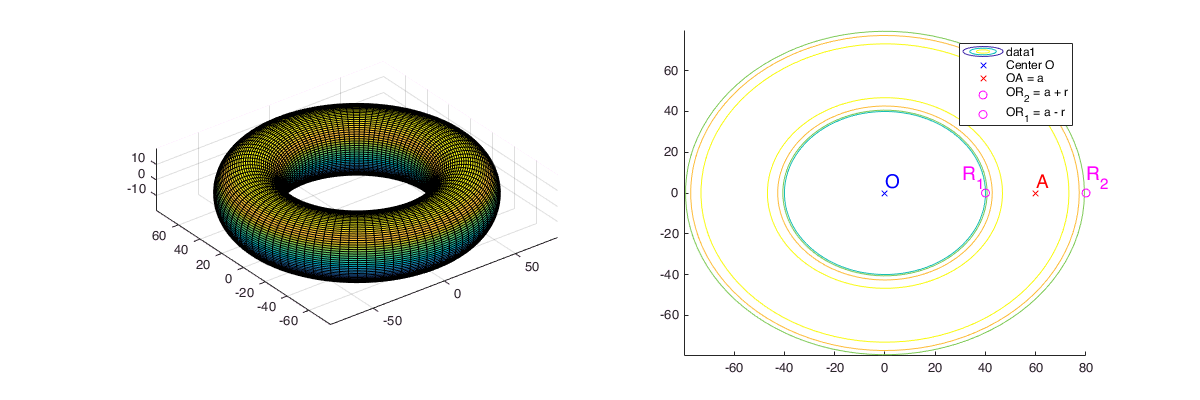

a = 60; r = 20;
[X, Y, Z] = shape(U, V, a, r);
figure('Position', [100, 100, 1200, 400]);

% Plot surf
subplot(1,2,1);
surf(X,Y,Z); axis equal

% Plot contour
subplot(1,2,2);
hold on
contour(X,Y,Z)

% Plot center O (0, 0)
plot(0,0,'bx', 'DisplayName','Center O');
text(0,0,'O','VerticalAlignment','bottom','Color','blue','FontSize',14);

% Plot a related point: A(60, 0)
plot(a,0,'rx', 'DisplayName','OA = a');
text(a,0,'A','VerticalAlignment','bottom','Color','red','FontSize',14);

% Plot r related points: R1(40, 0) & R2(80, 0)
plot(r+a,0,'mo', 'DisplayName','OR_2 = a + r');
text(r+a,0,'R_2','VerticalAlignment','bottom','Color','magenta','FontSize',14);

plot(a-r,0,'mo', 'DisplayName','OR_1 = a - r');
text(a-r,0,'R_1','VerticalAlignment','bottom','HorizontalAlignment','right','Color','magenta','FontSize',14);

legend('show');
hold off

**In the figure above:**

OA = a

R1R2 = 2r

OR1 = OA - AR1 = a - r

OR2 = OA + AR2 = a + r

Let's try different values of **a** and **r** and see if my guess is correct!

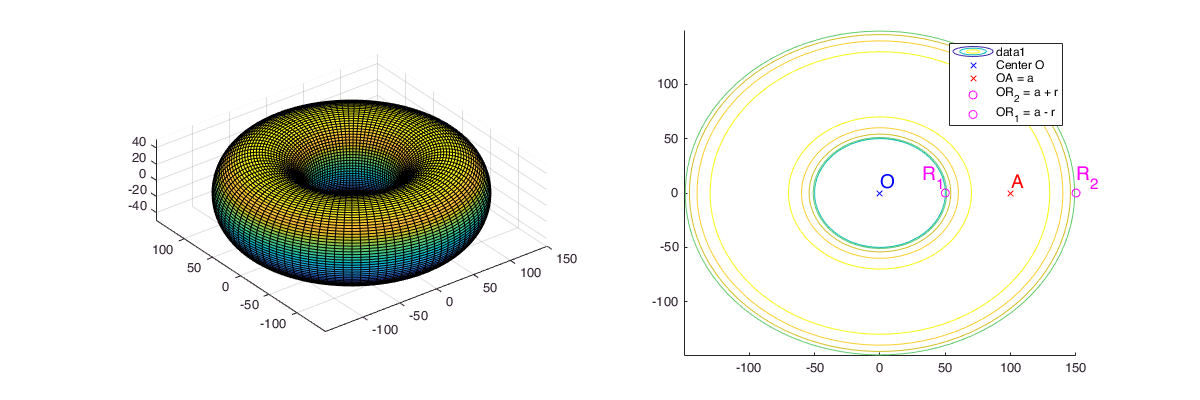

a = 100; r = 50;
[X, Y, Z] = shape(U, V, a, r);
figure('Position', [100, 100, 1200, 400]);

% Plot surf
subplot(1,2,1);
surf(X,Y,Z); axis equal

% Plot contour
subplot(1,2,2);
hold on
contour(X,Y,Z)

% Plot center O(0, 0)
plot(0,0,'bx', 'DisplayName','Center O');
text(0,0,'O','VerticalAlignment','bottom','Color','blue','FontSize',14);

% Plot a related point: A(100,0)
plot(a,0,'rx', 'DisplayName','OA = a');
text(a,0,'A','VerticalAlignment','bottom','Color','red','FontSize',14);

% Plot r related points: R1(50,0) & R2(50,0)
plot(r+a,0,'mo', 'DisplayName','OR_2 = a + r');
text(r+a,0,'R_2','VerticalAlignment','bottom','Color','magenta','FontSize',14);

plot(a-r,0,'mo', 'DisplayName','OR_1 = a - r');
text(a-r,0,'R_1','VerticalAlignment','bottom','HorizontalAlignment','right','Color','magenta','FontSize',14);

legend('show');
hold off

a = 100, r =50

A is at (100, 0)

R1 (50, 0)

R2 (50, 0)

p/s: I've validated that rings in the contour figure above are perfect circles, not ellipses by measuring the distance between O to the edges of the rings.

p/s 2: seems like bakers make donuts and donut holes using this function!

function [x,y,z] = sphereparam(u,v)
    x = sin(u).*cos(v);
    y = sin(u).*sin(v);
    z = cos(u);
end

function [x,y,z] = shape(u,v,a,r)
    x = (a + r.*cos(u)).*cos(v);
    y = (a + r.*cos(u)).*sin(v);
    z = r.*sin(u);
end